f0 = 50

f0 = 50

f1 = 250

f1 = 250

t1 = 2

t1 = 2

y = cos(2.*pi.*t.*(f0 + (f1 - f0)*t.^2/(3.*t1.^2)))

y =     1.0000    0.9993    0.9971    0.9934    0.9883    0.9817    0.9736    0.9642    0.9533    0.9410    0.9274    0.9123    0.8960    0.8783    0.8593    0.8391    0.8176    0.7949    0.7711    0.7461    0.7200    0.6929    0.6647    0.6356    0.6055    0.5746    0.5427    0.5101    0.4768    0.4427    0.4080    0.3727    0.3369    0.3005    0.2637    0.2266    0.1891    0.1513    0.1133    0.0751    0.0368   -0.0015   -0.0399   -0.0782   -0.1163   -0.1543   -0.1921   -0.2296   -0.2667   -0.3035


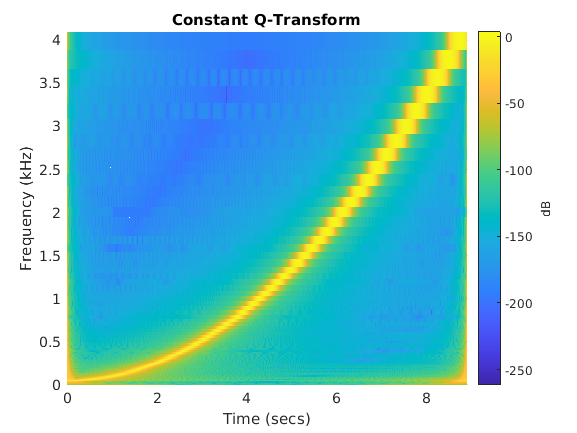


cqt(y,'SamplingFrequency',Fs)

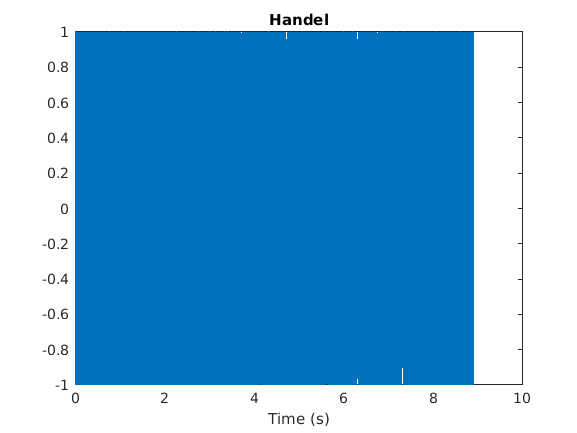

t = (0:length(y)-1)/Fs;
plot(t,y)
title('Handel')
xlabel('Time (s)')

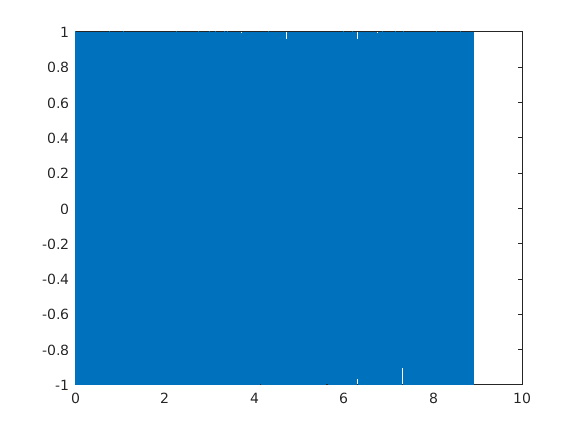


[cfs,~,g,fshifts] = cqt(y,'SamplingFrequency',Fs,'TransformType','sparse');


xrec = icqt(cfs,g,fshifts);

plot(t,xrec)